clear, close all;

% -------- Font Settings --------------------------------------------------
set(0,'defaultAxesFontSize',18);
set(0,'defaultAxesFontName','Times New Roman');
set(0,'defaultTextFontSize',18);
set(0,'defaultTextFontName','Times New Roman');

LW = 1;

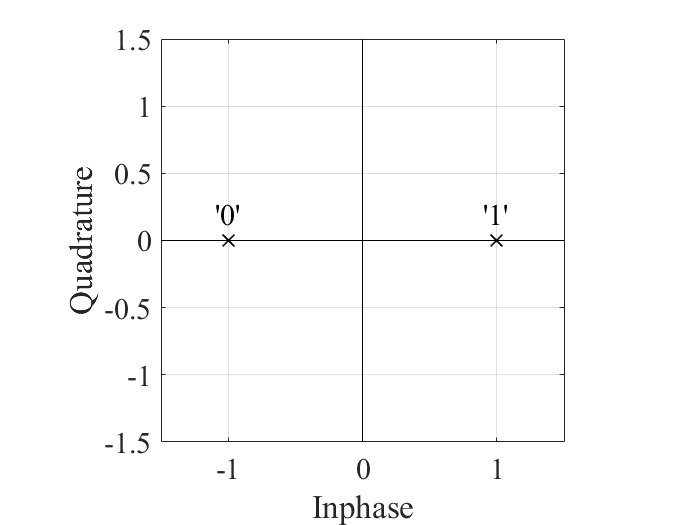

%%%%%%%%%%%%%%%%%%%%%
% Constellation (Tx)
%%%%%%%%%%%%%%%%%%%%%

x = [-1 1];
y = [0 0];

figure;
h = plot(x, y, 'kx', 'MarkerSize',10);hold on;
set(h, 'Linewidth', 1);
line([0 0], [-1.5 1.5], 'color', 'k');
line([-1.5 1.5], [0 0], 'color', 'k');
xlabel('Inphase','FontName','Times New Roman');
ylabel('Quadrature','FontName','Times New Roman');
text(0.9,0.2, '''1''');
text(-1.1,0.2, '''0''');
% AX = legend('Meas.', 'Sim', 2);
% LEG = findobj(AX,'type','text');
% set(LEG,'FontName', 'Times New Roman', 'FontSize',14);
grid on;
box on;
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
axis square

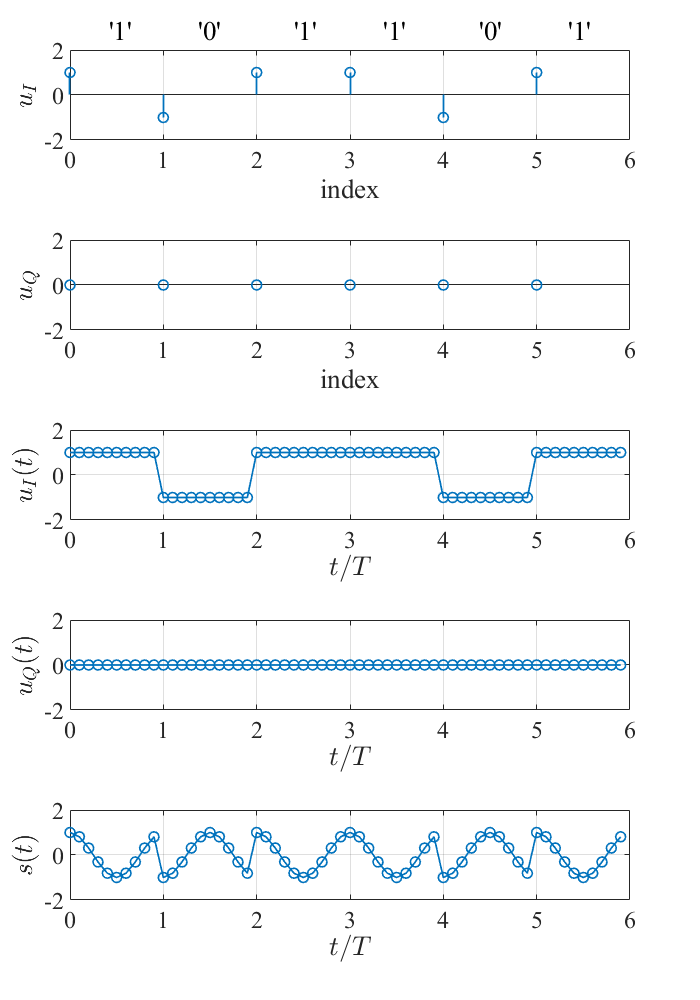

%%%%%%%%%%%%%%%
% Modulation
%%%%%%%%%%%%%%%

m = [1 0 1 1 0 1];        % ビット系列
M = length(m);            % シンボル数（QPSK：2ビット/シンボル)

fc = 100;                 % 搬送波周波数 [Hz]
R  = 100;                 % シンボルレート [symbols/sec]
T  = 1/R;                 % シンボル周期
Fs = R*10;                % サンプリング周波数
Ts = 1/Fs;                % サンプル周期

N  = T/Ts;                % シンボル当たりのサンプル数
n  = 0:M*N-1;
t  = n*Ts;                % 時間

car = exp(1j*2*pi*fc*t); % 搬送波（1周期/シンボル）

g_t = ones(1,N);          % パルス整形フィルタ

uI_t = [];
uQ_t = [];

for ii=1:M
    % 符号化（シンボルマッピング）
    sval = m(ii);
    switch sval
        case 0
            ph = pi;
        case 1
            ph = 0;
    end
    
    % 符号系列
    uI(ii) = cos(ph);
    uQ(ii) = sin(ph);
    
    % 基底帯域信号
    uI_t = [uI_t g_t*uI(ii)];
    uQ_t = [uQ_t g_t*uQ(ii)];
    
end

u   = uI_t + 1j*uQ_t;
% 帯域信号
s_t = real(car.*u);

f=figure;
f.Position = [488.0   57.8  560.0  800.2];
[ha] = tight_subplot(5,1,[.1 1],[.1 .05],[.1 .1]);

axes(ha(1));
h=stem(0:M-1, uI);
set(h, 'Linewidth', LW);
xlabel('index','FontName','Times New Roman');
ylabel('$$u_I$$','FontName','Times New Roman', 'interpreter', 'latex');
xlim([0 length(uI)]);
ylim([-2 2]);
title(strcat('''1''          ''0''           ''1''          ''1''           ''0''          ''1'''));
grid on
set(gca, 'xtick', 0:1:M);

axes(ha(2));
h=stem(0:M-1, uQ);
set(h, 'Linewidth', LW);
xlabel('index','FontName','Times New Roman');
ylabel('$$u_Q$$','FontName','Times New Roman', 'interpreter', 'latex');
xlim([0 length(uQ)]);
ylim([-2 2]);
grid on
set(gca, 'xtick', 0:1:M);

axes(ha(3));
h=plot(t/T, uI_t, '-o');
set(h, 'Linewidth', LW);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$u_I(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
%xlim([0 length(uI)]);
ylim([-2 2]);
grid on
set(gca, 'xtick', 0:1:M);

axes(ha(4));
h=plot(t/T, uQ_t, '-o');
set(h, 'Linewidth', LW);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$u_Q(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
%xlim([0 length(uQ0)]);
ylim([-2 2]);
grid on
set(gca, 'xtick', 0:1:M);

axes(ha(5));
h=plot(t/T, s_t, '-o');
set(h, 'Linewidth', LW);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$s(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
ylim([-2 2]);
grid on
set(gca, 'xtick', 0:1:M);

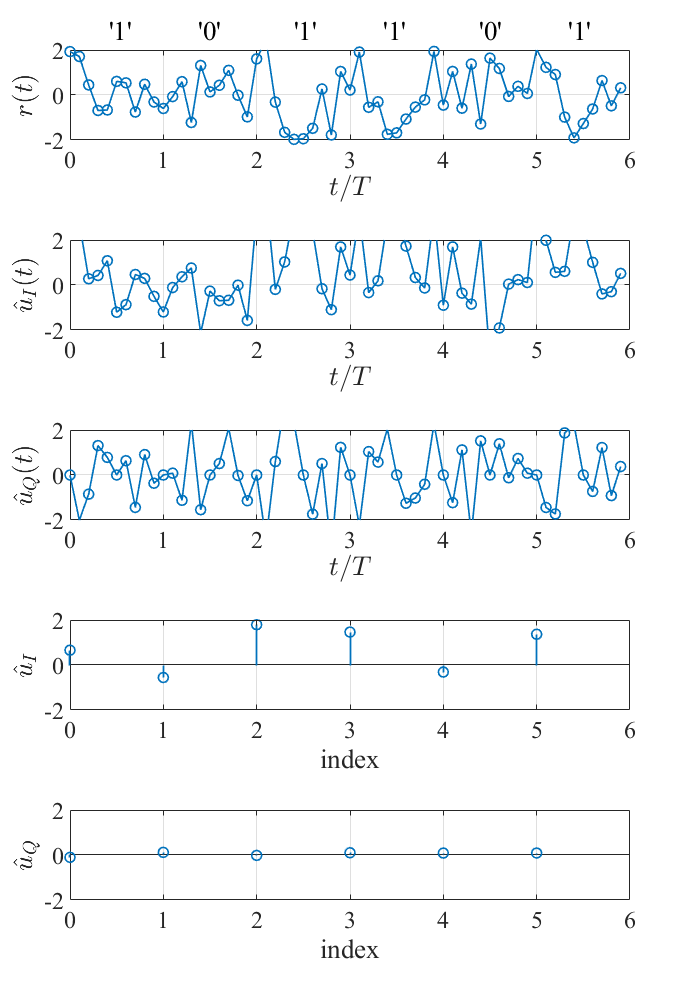


%%%%%%%%%%%%%%%
% De-Modulation
%%%%%%%%%%%%%%%

SNR = 0;
rt = s_t + 10^(-SNR/20)*randn(1,M*N); % SNR 6dB
rI = rt*2.*real(car);
rQ = -rt*2.*imag(car);
r_uI = [];
r_uQ = [];
for ii=1:M
    r_uI = [r_uI mean(rI((ii-1)*N+1:ii*N))];
    r_uQ = [r_uQ mean(rQ((ii-1)*N+1:ii*N))];
end

f=figure;
f.Position = [488.0   57.8  560.0  800.2];
[ha] = tight_subplot(5,1,[.1 1],[.1 .05],[.1 .1]);

axes(ha(1));
h=plot(t/T, rt, '-o');
set(h, 'Linewidth', LW);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$r(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
title(strcat('''1''          ''0''           ''1''          ''1''           ''0''          ''1'''));
ylim([-2 2]);
grid on
set(gca, 'xtick', 0:1:M);

axes(ha(2));
h=plot(t/T, rI, '-o');
set(h, 'Linewidth', LW);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$\hat{u}_I(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
%xlim([0 length(uI)]);
ylim([-2 2]);
grid on
set(gca, 'xtick', 0:1:M);

axes(ha(3));
h=plot(t/T, rQ, '-o');
set(h, 'Linewidth', LW);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$\hat u_Q(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
%xlim([0 length(uQ0)]);
ylim([-2 2]);
grid on
set(gca, 'xtick', 0:1:M);

axes(ha(4));
h=stem(0:M-1, r_uI);
set(h, 'Linewidth', LW);
xlabel('index','FontName','Times New Roman');
ylabel('$$\hat{u}_I$$','FontName','Times New Roman', 'interpreter', 'latex');
xlim([0 length(r_uI)]);
ylim([-2 2]);
grid on
set(gca, 'xtick', 0:1:M);

axes(ha(5));
h=stem(0:M-1, r_uQ);
set(h, 'Linewidth', LW);
xlabel('index','FontName','Times New Roman');
ylabel('$$\hat{u}_Q$$','FontName','Times New Roman', 'interpreter', 'latex');
xlim([0 length(r_uQ)]);
ylim([-2 2]);
grid on
set(gca, 'xtick', 0:1:M);

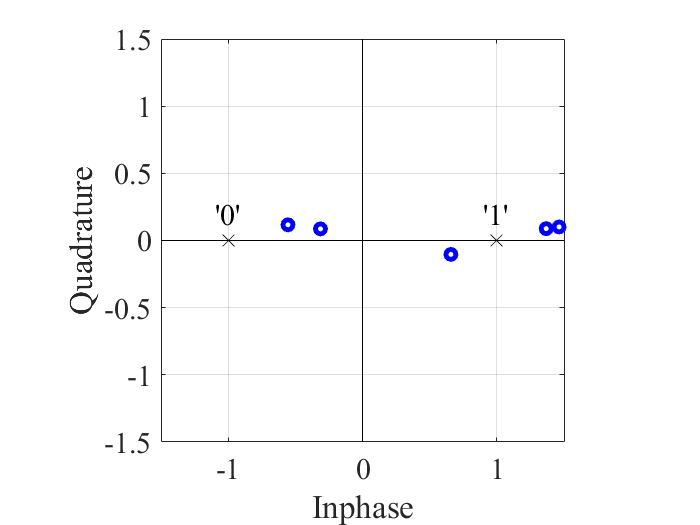

%%%%%%%%%%%%%%%%%%%%%
% Constellation (Rx)
%%%%%%%%%%%%%%%%%%%%%
figure;
h = plot(r_uI, r_uQ, 'bo');hold on;
set(h, 'Linewidth', 3);
plot(x, y, 'kx', 'MarkerSize',10);
line([0 0], [-1.5 1.5], 'color', 'k');
line([-1.5 1.5], [0 0], 'color', 'k');
xlabel('Inphase','FontName','Times New Roman');
ylabel('Quadrature','FontName','Times New Roman');
text(0.9,0.2, '''1''');
text(-1.1,0.2, '''0''');
% AX = legend('Meas.', 'Sim', 2);
% LEG = findobj(AX,'type','text');
% set(LEG,'FontName', 'Times New Roman', 'FontSize',14);
grid on;
box on;
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
axis square